110202058 Furkan İÇÖZ					

# **Giunta Function **

**(Sürekli, Diferansiyeli alınabilir, ayrık, ölçeklenebilir ve çok kipli)**

	 
$$f\left(x\right)=0\ldotp 6+\sum_{i=1}^{2} \left\lbrack \mathrm{sin}\left(\frac{16}{15}x_i -1\right)+{\mathrm{sin}}^2 \left(\frac{16}{15}x_i -1\right)+\frac{1}{50}\mathrm{sin}\left(4\left(\frac{16}{15}X_i -1\right)\right)\right\rbrack$$



$$-1\le x_i \le 1\text{ }\text{aral}\i ğ\i \text{nda}\ldotp {\text{ }x}^∗ =f\left(0\ldotp 45834282,\text{ }0\ldotp 45834282\right)\text{ }\text{değeri}\text{ }\text{için}\text{ }\text{global}\text{ }\text{minimum}\text{ }\text{değeri}\text{ }f\left(x^∗ \right)=0\ldotp 060447\text{ }\text{olur}\ldotp$$


clear
clc
warning off

Değer aralıklarını belirliyoruz:

x1min=-1;
x1max=1;
x2min=-1;
x2max=1;

R=100; % steps resolution
x1=x1min:(x1max-x1min)/R:x1max;
x2=x2min:(x2max-x2min)/R:x2max;

fonksiyonun toplam döngüsü:

for j=1:length(x1)
    
    for i=1:length(x2)
        h1(i)=(sin(1-(16/15)*x1(j)))^2+(sin(1-(16/15)*x2(i)))^2;
        h2(i)=0.02*(sin(4-(64/15)*x1(j))+sin(4-(64/15)*x2(i)));
        h3(i)=sin(1-(16/15)*x1(j))+sin(1-(16/15)*x2(i));
        f(i)=0.6+h1(i)-h2(i)-h3(i);
    end
    f_tot(j,:)=f;
end

görsel çizimler:

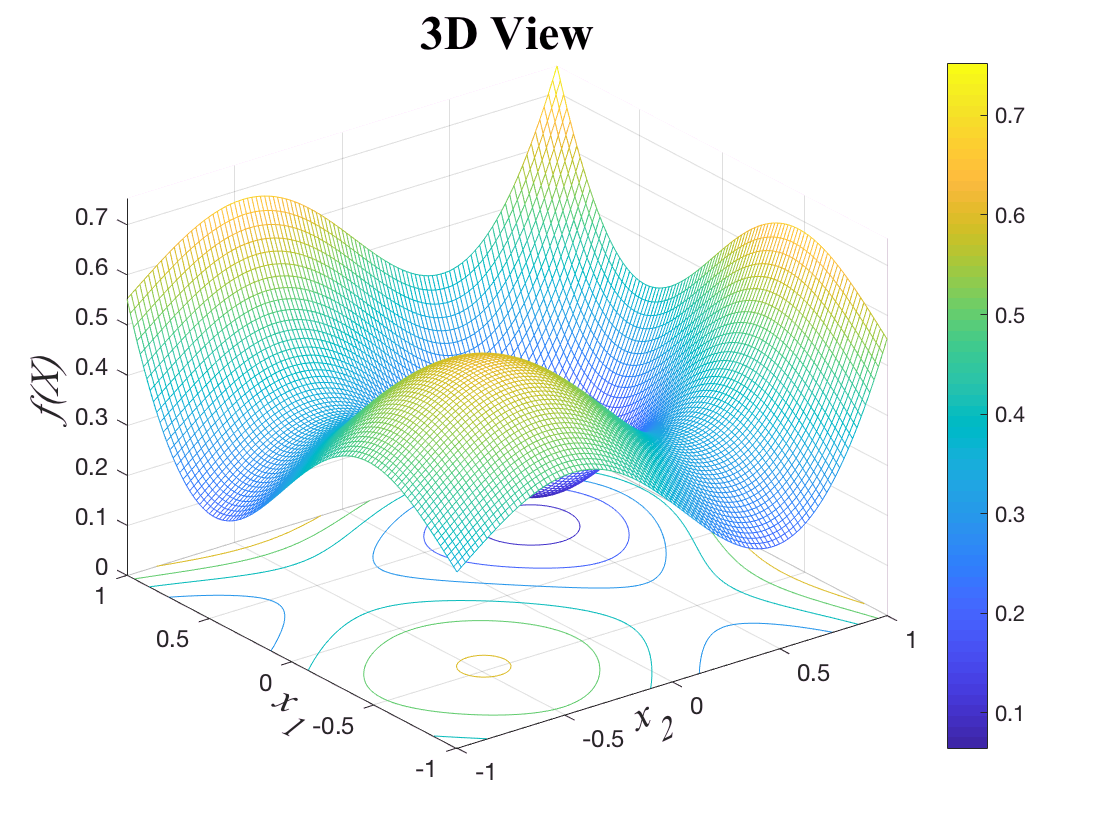

figure(1)
meshc(x1,x2,f_tot);colorbar;set(gca,'FontSize',12);
xlabel('x_2','FontName','Times','FontSize',20,'FontAngle','italic');
set(get(gca,'xlabel'),'rotation',25,'VerticalAlignment','bottom');
ylabel('x_1','FontName','Times','FontSize',20,'FontAngle','italic');
set(get(gca,'ylabel'),'rotation',-25,'VerticalAlignment','bottom');
zlabel('f(X)','FontName','Times','FontSize',20,'FontAngle','italic');
title('3D View','FontName','Times','FontSize',24,'FontWeight','bold');

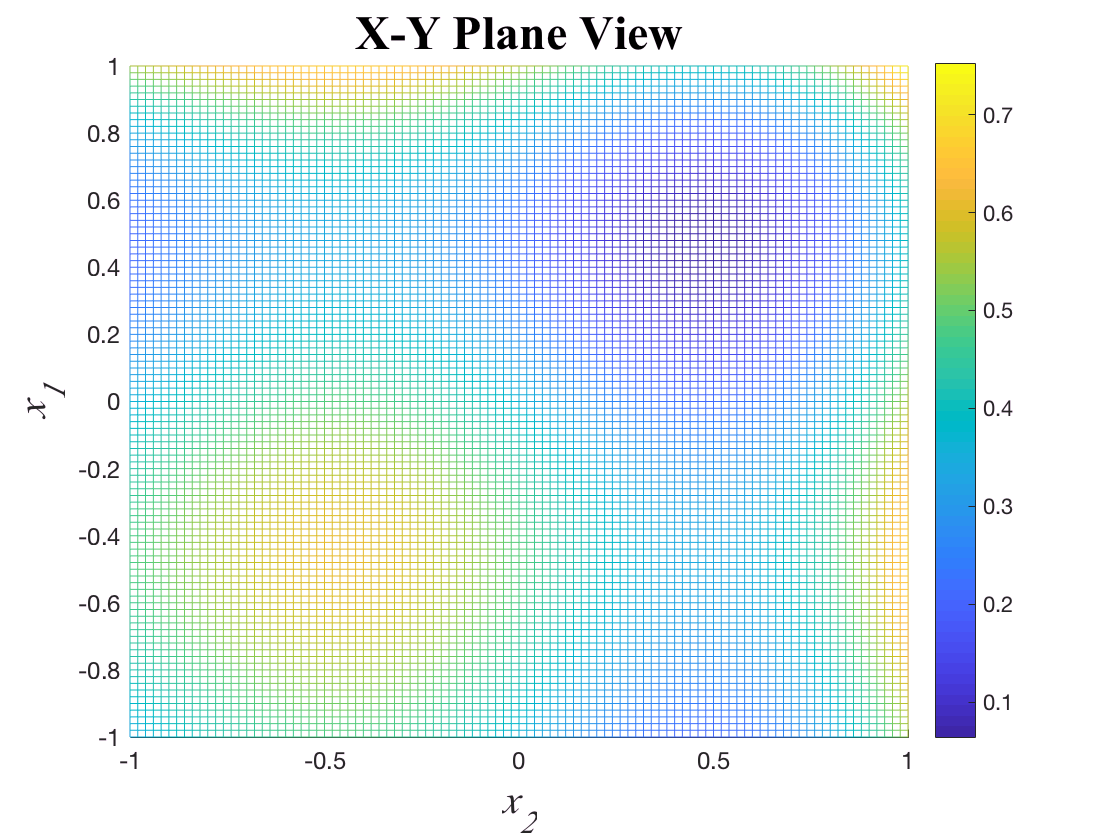


figure(2)
mesh(x1,x2,f_tot);view(0,90);colorbar;set(gca,'FontSize',12);
xlabel('x_2','FontName','Times','FontSize',20,'FontAngle','italic');
ylabel('x_1','FontName','Times','FontSize',20,'FontAngle','italic');
zlabel('f(X)','FontName','Times','FontSize',20,'FontAngle','italic');
title('X-Y Plane View','FontName','Times','FontSize',24,'FontWeight','bold');

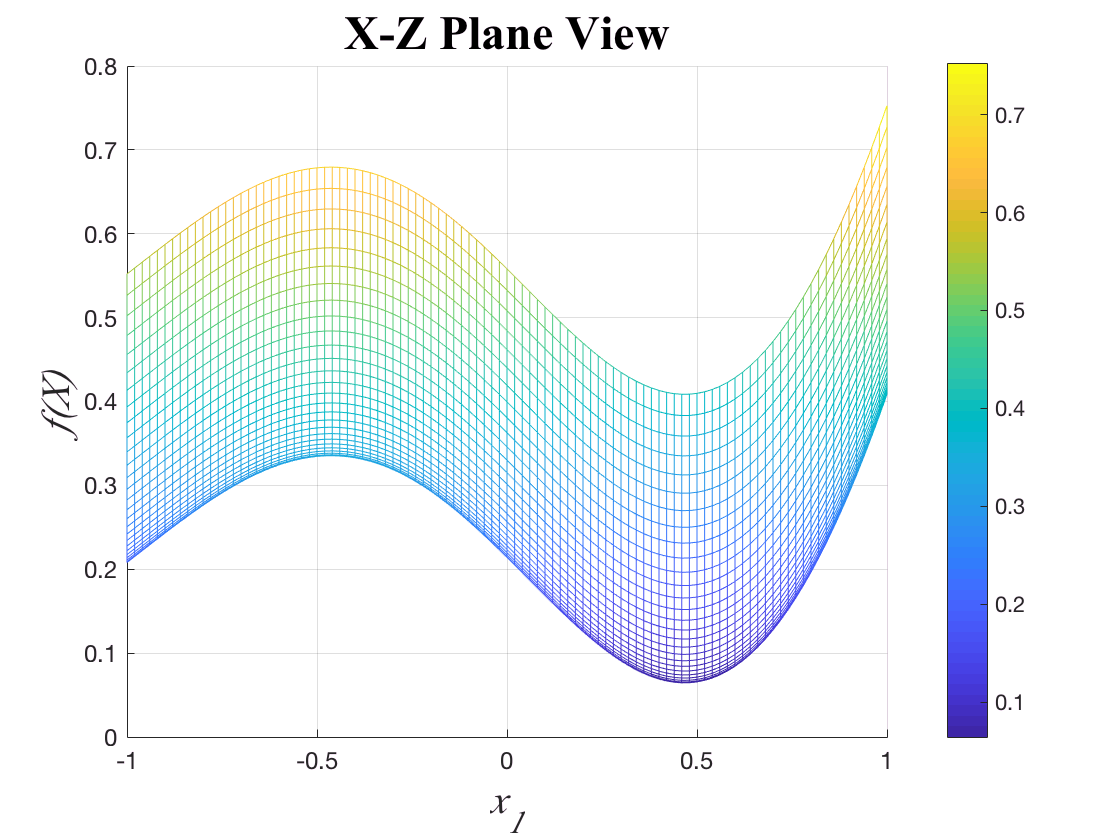


figure(3)
mesh(x1,x2,f_tot);view(90,0);colorbar;set(gca,'FontSize',12);
xlabel('x_2','FontName','Times','FontSize',20,'FontAngle','italic');
ylabel('x_1','FontName','Times','FontSize',20,'FontAngle','italic');
zlabel('f(X)','FontName','Times','FontSize',20,'FontAngle','italic');
title('X-Z Plane View','FontName','Times','FontSize',24,'FontWeight','bold');

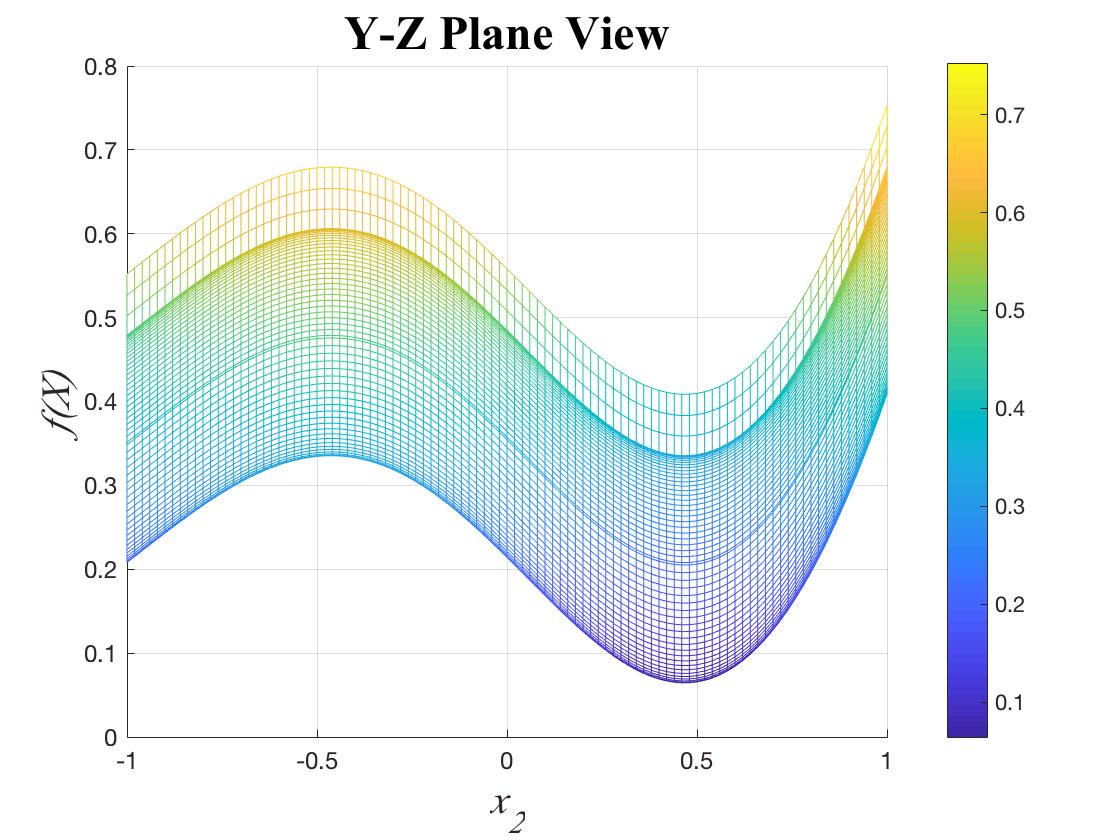


figure(4)
mesh(x1,x2,f_tot);view(0,0);colorbar;set(gca,'FontSize',12);
xlabel('x_2','FontName','Times','FontSize',20,'FontAngle','italic');
ylabel('x_1','FontName','Times','FontSize',20,'FontAngle','italic');
zlabel('f(X)','FontName','Times','FontSize',20,'FontAngle','italic');
title('Y-Z Plane View','FontName','Times','FontSize',24,'FontWeight','bold');

## **Xin-She Yang (Function 03)**

(Ayrıklaştırılamayan)

**Denklem**:


$$\begin{array}{l}
f\left(x\right)=\left\lbrack e^{-\sum_{i=1}^{D} \left(x_{\frac{i}{\beta }} \right)2m} -2e^{-\sum_{i=1}^{D} {\left(x_i \right)}^2 } \ldotp \prod_{i=1}^{D} {\mathrm{cos}}^2 \left(x_i \right)\right\rbrack \\
-20\le x_i \le 20\text{ }\mathrm{aral}\i ğ\i \mathrm{nda}\ldotp m=5\text{ }\mathrm{ve}\text{ }\beta =15\text{ }\mathrm{için}\text{ }x^∗ =f\left(0,\ldotp \ldotp \ldotp ,0\right)\text{ }\mathrm{olursa}\text{ }\mathrm{global}\text{ }\mathrm{minimum}\text{ }f\left(x^∗ \right)=-1\text{ }\mathrm{olur}\ldotp 
\end{array}$$


clear
clc
warning off

değerler:

x1min=-20;
x1max=20;
x2min=-20;
x2max=20;
D = 10;
m = 5;
beta=15

R=10; % steps resolution
x1=x1min:(x1max-x1min)/R:x1max;
x2=x2min:(x2max-x2min)/R:x2max;

fonksiyon:

% scores = exp(-sum((x / beta).^(2*m), 2)) - (2 * exp(-sum(x .^ 2, 2)) .* prod(cos(x) .^ 2, 2));
for i=1:length(x1)
for j=1:D
    ht1(j) = (x1(j)/beta)^(2 * m);
end
for j=1:D
    ht2(j) = (x1(j))^2
end
for j=1:D
    ht3(j)=(cos(x1(j)))^2
end
f_tot(i,:)=exp(-(sum(ht1))) - 2 * exp(-(sum(ht2))) * prod(ht3)
end
disp(f_tot)